# Color Classification

Benjamin Hall

CS-481 Artificial Intelligence

Dr. Farmer

2023, March 20

## Reset Workspace

clc
clear

## Import and Plot Classification Data

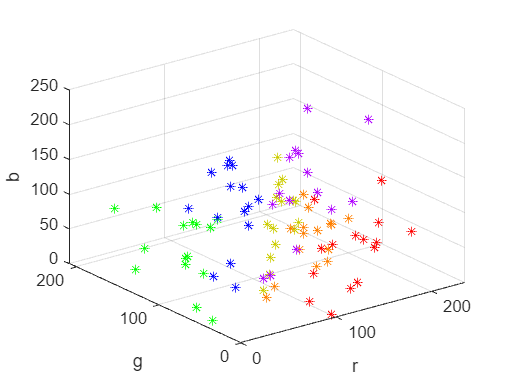

% plot colors
colors = ["red", "green", "blue", "#FF7F00", "#CCCC00", "#AF00FF"];
% import rgb data
data_rgb = importfile("color_training_full.dat");

% group data into classifications
classes_rgb = group_classes(data_rgb);

% plot the classes
scatter3_classes(classes_rgb, colors, ['r', 'g', 'b']);

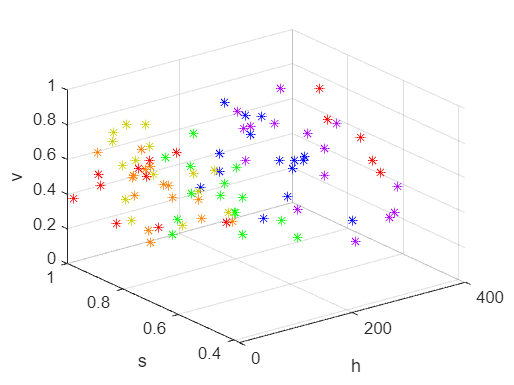


% import hsv data
data_hsv = importfile("color_training_full_hsv.dat");

% group data into classifications
classes_hsv = group_classes(data_hsv);

% plot the classes
scatter3_classes(classes_hsv, colors, ["h", "s", "v"]);

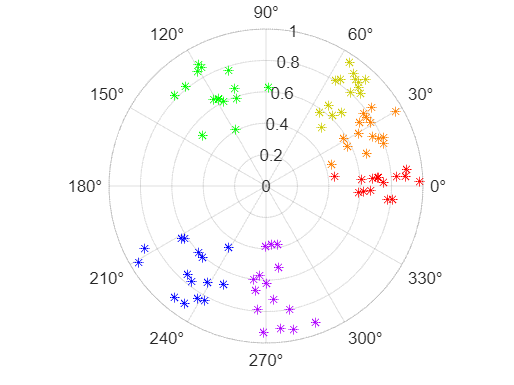


% plot the classes' hue and saturation values in polar form
polarscatter_classes(classes_hsv, colors);

### Classification Grouping Function

function classes = group_classes(data)
class_sz = size(data,1) / 6;

% group data into classifications in this order:
class_red = zeros(class_sz,3);
class_green = zeros(class_sz,3);
class_blue = zeros(class_sz,3);
class_orange = zeros(class_sz,3);
class_yellow = zeros(class_sz,3);
class_purple = zeros(class_sz,3);

% file has the same amount of data for each color
% in the order listed above
for i = 1:class_sz
    idx = i;
    class_red(idx,:) = data(i,:);
end
for i = (class_sz + 1):(2*class_sz)
    idx = i - class_sz;
    class_green(idx,:) = data(i,:);
end
for i = (2*class_sz + 1):(3*class_sz)
    idx = i - 2*class_sz;
    class_blue(idx,:) = data(i,:);
end
for i = (3*class_sz + 1):(4*class_sz)
    idx = i - 3*class_sz;
    class_orange(idx,:) = data(i,:);
end
for i = (4*class_sz + 1):(5*class_sz)
    idx = i - 4*class_sz;
    class_yellow(idx,:) = data(i,:);
end
for i = (5*class_sz + 1):(6*class_sz)
    idx = i - 5*class_sz;
    class_purple(idx,:) = data(i,:);
end

% put classes into a cell
classes = {class_red; class_green; class_blue;
    class_orange; class_yellow; class_purple};
end

### Classification Plot Function

function scatter3_classes(classes, colors, axis_names)
%% Plots 3-D classes on a scatter plot with the specified colors.

for i = 1:size(classes, 1)
    scatter3(classes{i}(:,1), classes{i}(:,2), classes{i}(:,3), "Marker", "*", "MarkerEdgeColor", colors(i));
    hold on;
end
xlabel(axis_names(1));
ylabel(axis_names(2));
zlabel(axis_names(3));
hold off;
end

### Classification Polar Plot Function

function polarscatter_classes(classes, colors)
%% Plots 2-D classes on a polar scatter plot with the specified colors.

for i = 1:size(classes, 1)
    polarscatter(deg2rad(classes{i}(:,1)), classes{i}(:,2), "Marker", "*", "MarkerEdgeColor", colors(i));
    hold on;
end
hold off;
end

### Import File Function


function read_3d_data = importfile(filename)
%IMPORTFILE Import data from a text file
%  DATA = IMPORTFILE(FILENAME) reads data from text file
%  FILENAME.  Returns the numeric data.
%
%  Example:
%  data = importfile("color_training_full.dat");
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 04-Mar-2023 23:06:10

%% Input handling

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
%opts.DataLines = [1, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["x", "y", "z"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Import the data
read_3d_data = readtable(filename, opts);

%% Convert to output type
read_3d_data = table2array(read_3d_data);
end